## In the name of Allah

## Project 3:

## Hossein Alizadeh Piralidehi 810100522

### Problem considerations:


$$\begin{array}{l}
\mathrm{charging}\;\mathrm{energy}:c_{t,i} \ge 0\;\;\;\;\;\;t=1,\ldotp \ldotp \ldotp ,T\;\;\;\;i=1,\ldotp \ldotp \ldotp ,N\\
\sum_{i=1}^N c_{t,i} \le C_{\max } \;\;\;\;\;t=1,\ldotp \ldotp \ldotp ,T\\
\mathrm{stage}\;\mathrm{of}\;\mathrm{charge}:\;q_{t,i} \ge 0\;\;\;\;t=1,\ldotp \ldotp \ldotp ,T+1\;\;\;i=1,\ldotp \ldotp \ldotp ,N\\
\mathrm{initial}\;\mathrm{vehiicle}\;\mathrm{charges}\;q_{1,i} \;\;\mathrm{are}\;\mathrm{given}\ldotp \\
\mathrm{charging}\;\mathrm{dynamics}:\;q_{t+1,i} =q_{t,i} +c_{t,i} \;\;\;\;t=1,\ldotp \ldotp \ldotp ,T\;\;\;i=1,\ldotp \ldotp \ldotp ,N\\
\mathrm{target}\;\mathrm{minimum}\;\mathrm{charge}\;\mathrm{level}:\;q_{t,i}^{\mathrm{tar}} \in R_+ \;\;\;t=1,\ldotp \ldotp \ldotp ,T+1\;\;\;\;\;\;\;q_{t+1,i}^{\mathrm{tar}} \ge q_{t,i}^{\mathrm{tar}} \\
\mathrm{charging}\;\mathrm{shortfall}:\;s_{t,i} ={\left(q_{t,i}^{\mathrm{tar}} -q_{t,i} \right)}_+ \\
\mathrm{and}\;\mathrm{objective}\;\mathrm{is}\;\mathrm{minimization}\;\mathrm{mean}\;\mathrm{square}\;\mathrm{shortfall}:\\
f_0 \left(c,q\right)=\frac{1}{N\left(T+1\right)}\sum_{t=1}^{T+1} \sum_{i=1}^N s_{t,i}^2 
\end{array}$$


### Description:

to have a convex optimization problem, we rewrite this problem as below:


$$$$


As described above, there is a optimization problem on finding charging energy of batteries, in each time period for each vehicle.

objective is in form of quadratic, $\;s_{t,i}$ are maximum of two convex functions so it is convex. finally objective will be convex.

there are three constraints in this problem:

    $c_{t,i} \ge 0\;$   half space $\to \textrm{convex}$

    $\sum_{i=1}^N c_{t,i} \le C_{\max }$   half space $\to \textrm{convex}$

    
$$\;q_{t+1,i} =q_{t,i} +c_{t,i}$$


### Simulation with given parameters:

load parameters

clc;clear;close all;

N = 4; T = 90;
C_max = 3;



gamma = [0.5 0.3 2 0.6];
q_des = [60 100 75 125];
q_tar = ((1:T+1).'/(T+1)).^gamma .* q_des;
q_hat = q_tar - [20 0 30 25];

q = zeros(T+1, N); q(1, :) =  [20 0 30 25];

solve convex problem using cvx toolbox

cvx_begin
    variables c(T, N);
    for t = 1 : T+1
        for i = 1 : N
            s_squared(t, i) =  pow_pos(q_hat(t,i) - ones(1,t-1)*c(1:t-1, i), 2);
        end
    end
    minimize( sum(sum(s_squared)) / ((T+1)*N) );
    subject to
        sum(c, 2) <= C_max;
        c(:) >= 0;
cvx_end

 
Calling SDPT3 4.0: 1890 variables, 810 equality constraints
------------------------------------------------------------

 num. of constraints = 810
 dim. of sdp    var  = 720,   num. of sdp  blk  = 360
 dim. of linear var  = 810
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.7e+02|8.1e+02|1.0e+07| 1.997802e+02  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.558|0.774|1.6e+02|1.8e+02|4.6e+06| 3.498047e+02 -1.430102e+04| 0:0:00| spchol  1  1 
 2|0.537|0.746|7.6e+01|4.7e+01|2.5e+06| 7.479596e+02 -2.106065e+04| 0:0:00| spchol  1  1 
 3|0.588|0.735|3.1e+01|1.2e+01|1.3e+06| 1.733105e+03 -2.534799e+04| 0:0:00| spchol  1  

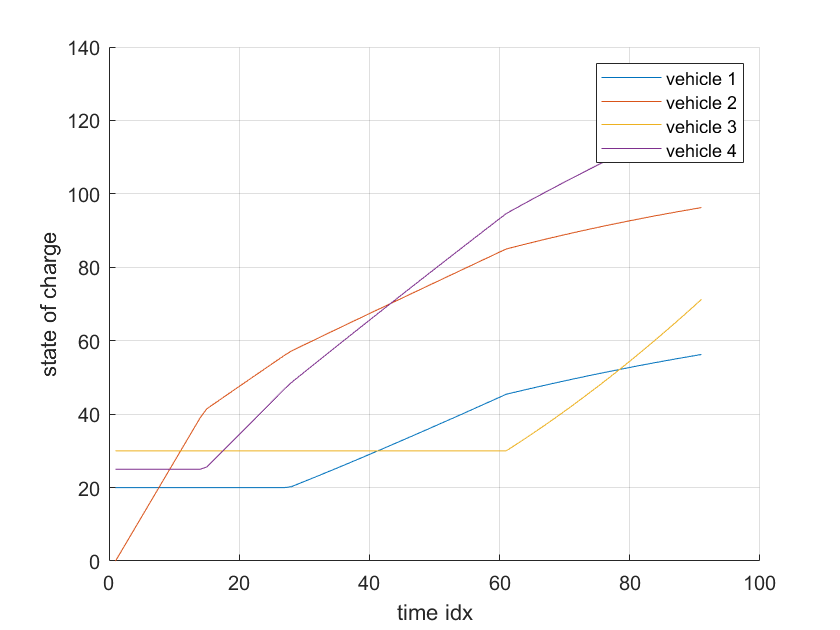

for t = 2 : T + 1
    q(t, :) = q(t-1, :) + c(t-1, :);
end
figure
hold on
grid on
for i = 1 : N
    plot(q(:, i))
end
xlabel('time idx')
ylabel('state of charge')
legend('vehicle 1', 'vehicle 2', 'vehicle 3', 'vehicle 4')

disp("Objective value: " + sum(sum(s_squared))/((T+1)*N))

Objective value: 78.503


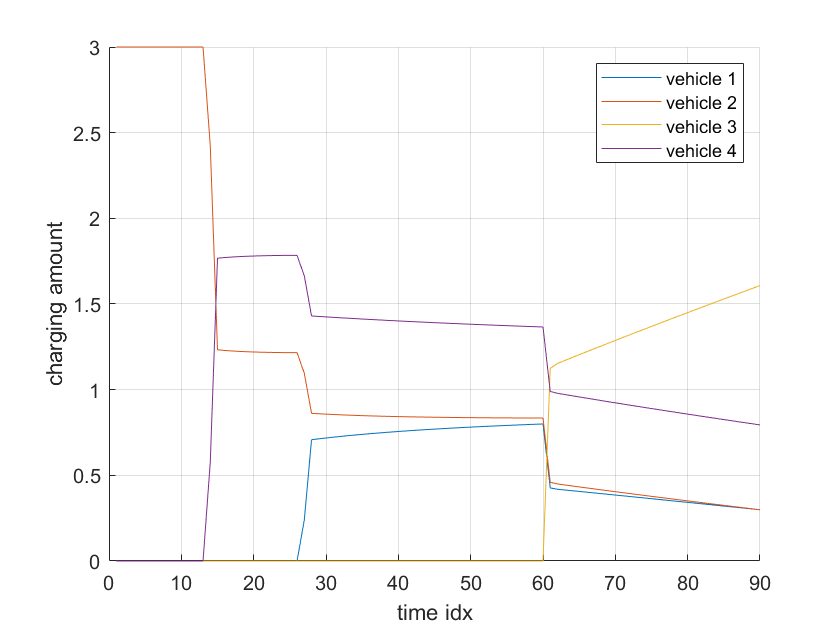

figure
hold on
grid on
for i = 1 : N
    plot(c(:, i))
end
legend('vehicle 1', 'vehicle 2', 'vehicle 3', 'vehicle 4')
xlabel('time idx')
ylabel('charging amount')

## Solve constant charging problem

theta = (q_des - q(1, :))/sum((q_des - q(1, :)));
c_cons = theta * C_max; c_cons = repmat(c_cons, T, 1);
for t = 1 : T+1
    for i = 1 : N
%         s_squared(t, i) = max( c_cons(1:t-1, i)'*ones(t-1)*c_cons(1:t-1, i) - 2*q_hat(t,i)*ones(1,t-1)*c_cons(1:t-1, i), 0);
        s_squared_cons(t, i) = pow_pos( q_hat(t,i) - ones(1, t-1)*c_cons(1:t-1, i), 2);
    end
end

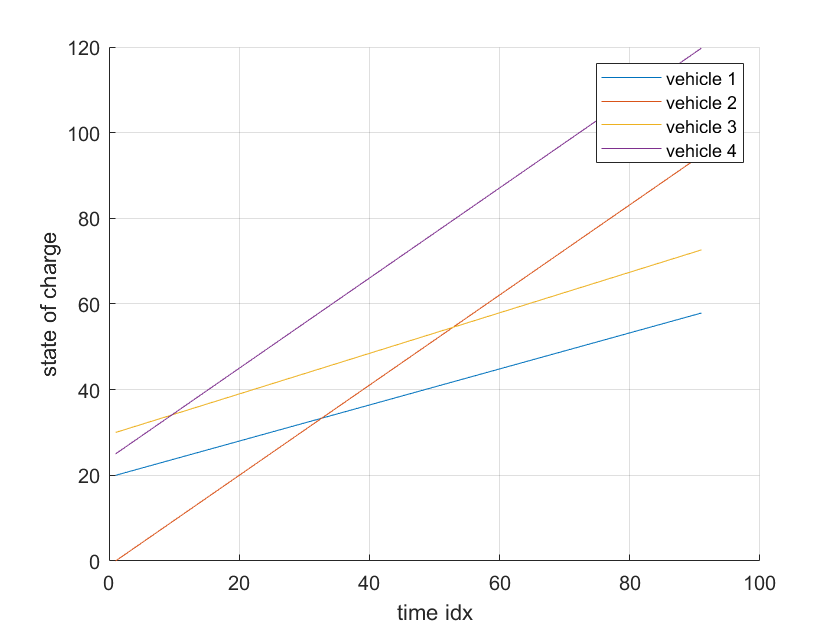

q_cons(1,:) = q(1,:);
q_cons(2 : T + 1, :) = q_cons(1 : T , :) + c_cons(1 : T , :);

figure
hold on
grid on
for i = 1 : N
    plot(q_cons(:, i))
end
xlabel('time idx')
ylabel('state of charge')
legend('vehicle 1', 'vehicle 2', 'vehicle 3', 'vehicle 4')

disp("Objective value for constant charging: " + sum(sum(s_squared_cons))/((T+1)*N))

Objective value for constant charging: 278.2112


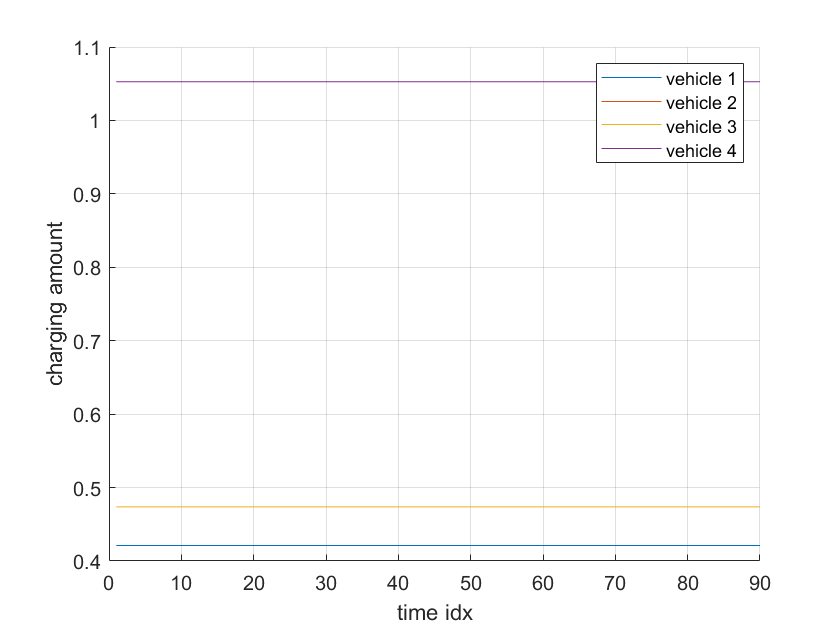

figure
hold on
grid on
for i = 1 : N
    plot(c_cons(:, i))
end
legend('vehicle 1', 'vehicle 2', 'vehicle 3', 'vehicle 4')
xlabel('time idx')
ylabel('charging amount')